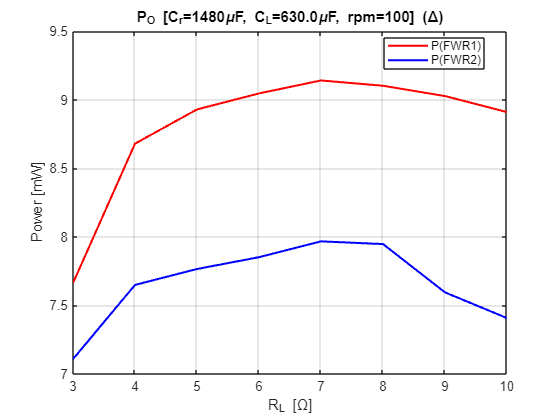


% Dati misurati (D1_100rpm.csv, D2_100rpm.csv - tabella "C = 630 uF"):
% sweep della resistenza di carico R_L, C_m e rpm fissi, per i due bridge FWR-Delta.
% CORREZIONE D2 a R_L = 4 Ohm: il CSV originale riportava Pi = 35.041 mW, circa un
% ordine di grandezza sotto le celle vicine (377.841 a R=3, 336.935 a R=5): errore di
% esportazione della virgola decimale. Valore corretto moltiplicando per 10 (350.41),
% in linea con l'andamento delle celle adiacenti.

C_r = 1480e-6;     % F - condensatore di filtro/raddrizzatore, fisso
C_L = 630e-6;      % F - condensatore di compensazione C_m, fisso durante lo sweep
rpm_b1 = 100;      % rpm fisso durante lo sweep

R_L = [3 4 5 6 7 8 9 10];   % Ohm (asse x)

Po_b1_mW = [76.623 86.790 89.284 90.450 91.395 91.008 90.259 89.090];
Pi_b1_mW = [381.131 363.467 341.982 322.266 304.756 289.514 273.883 261.595];

Po_b2_mW = [71.084 76.492 77.653 78.513 79.668 79.470 75.950 74.075];
Pi_b2_mW = [377.841 350.41 336.935 317.717 303.277 287.889 271.843 259.005];   % R=4Ohm corretto (CSV: 35.041, anomalo)

P_real_b1 = Po_b1_mW/1000;
P_real_b2 = Po_b2_mW/1000;

P_in_b1 = Pi_b1_mW/1000;
P_in_b2 = Pi_b2_mW/1000;


figure;
plot(R_L, P_real_b1*1000/10, 'r-', 'LineWidth', 1.5);hold on;
plot(R_L, P_real_b2*1000/10, 'b-', 'LineWidth', 1.5);
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, C_L=%.1f\\muF, rpm=%.0f] (FWR-\\Delta)', C_r*1e6,C_L*1e6,rpm_b1));
xlabel('R_L [\Omega]');
ylabel('Power [mW]');
xlim([min(R_L), max(R_L)]);
legend(["P(FWR1)","P(FWR2)"], "Location","best");
hold off;

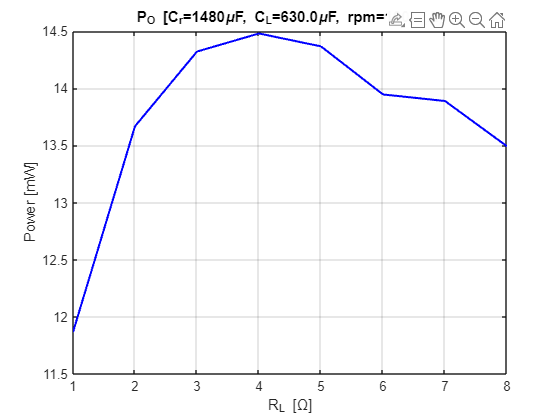


% figure;
% plot(R_L, (P_real_b1+P_real_b2)*1000, 'b-', 'LineWidth', 1.5)
% grid on;
% title(sprintf('P_O [C_r=%.0f\\muF, C_L=%.1f\\muF, rpm=%.0f] (\\Delta)', C_r*1e6,C_L*1e6,rpm_b1));
% xlabel('R_L [\Omega]');
% ylabel('Power [mW]');
% xlim([min(R_L), max(R_L)]);
% hold off;


% Dati misurati con i due bridge FWR-Delta gia' collegati in parallelo
% (D_1+2_100rpm.csv), C_m = 630 uF fisso, rpm = 100: mostrati in una figura separata
% perche' il range di R_L di questa misura (1-8 Ohm) e' diverso da quello dei bridge
% singoli sopra (3-10 Ohm). Il CSV non riporta Pi per questa misura (solo Po).

R_L_tot = [1 2 3 4 5 6 7 8];   % Ohm (asse x, misura con i due bridge in parallelo)

Po_tot_mW = [118.662 136.666 143.203 144.783 143.654 139.451 138.877 134.917]/10;

P_real_tot_meas = Po_tot_mW/1000;

figure;
plot(R_L_tot, P_real_tot_meas*1000, 'b-', 'LineWidth', 1.5)
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, C_L=%.1f\\muF, rpm=%.0f] (FWR-\\Delta)', C_r*1e6,C_L*1e6,rpm_b1));
xlabel('R_L [\Omega]');
ylabel('Power [mW]');
xlim([min(R_L_tot), max(R_L_tot)]);
hold off;